% Load Mixed Audio
[X, fs] = audioread('./data/mixed_audio_2mix_v2.wav');  % X: (samples x channels)
disp('Mixed audio dimension:');

Mixed audio dimension:



% 오디오 크기 출력
disp(size(X)); 

    10625664           2




% player = audioplayer(X, fs);
% play(player)
% stop(player)

% ICA는 (채널 x 샘플) 형식이므로 전치(transpose)
X = X';  % (channels x samples)

% ================= ICA 수행 =================
% EEGLAB의 runica 함수를 사용하여 ICA 수행
% weights: ICA 가중치 행렬, sphere: sphering 행렬
[weights, sphere] = runica(X);


Input data size [2,10625664] = 2 channels, 10625664 frames/nFinding 2 ICA components using logistic ICA.
Decomposing 2656416 frames per ICA weight ((4)^2 = 10625664 weights, Initial learning rate will be 0.000937752, block size 81.
Learning rate will be multiplied by 0.9 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -0.999985 to 0.999985
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ...
step 1 - lrate 0.000938, wchange 0.22040972, angledelta  0.0 deg
step 2 - lrate 0.000938, wchange 0.00196146, angledelta  0.0 deg
step 3 - lrate 0.000938, wchange 0.00572780, angledelta 68.9 deg
step 4 - lrate 0.000844, wchange 0.00469849, angledelta 156.1 deg
step 5 - lrate 0.000760, wchange 0.00191228, angledelta 104.4 deg
step


% 추정된 source 계산
% ICA 결과로 얻은 분리된 오디오 신호들
X_hat = weights * sphere * X;
% ============================================

% 정규화 (Normalize to [-1, 1])
X_hat = X_hat ./ max(abs(X_hat), [], 2);

% player_estimated1 = audioplayer(X_hat(1, :), fs);
% play(player_estimated1);
% stop(player_estimated1);

% Load Original Sources
audio_dir = './data/example_sound_sources/example_sound_sources/';
files = dir(fullfile(audio_dir, '*.wav'));

% 초기화: 최소 길이를 찾기 위한 변수, sampling rate 저장 배열 등
min_len = inf;
fs_all = zeros(length(files),1); % 각 파일의 샘플링 레이트 저장
S = []; % 원본 소스들을 저장할 행렬

for i = 1:length(files)
    [y, fs_] = audioread(fullfile(audio_dir, files(i).name));
    y = y(:,1);  % mono 변환(한 채널만 사용)
    fs_all(i) = fs_;
    min_len = min(min_len, length(y));
    S = [S; y'];  % 가로 방향으로 이어 붙임(source x samples 형태)
end

% Sampling rate 확인
if ~all(fs_all == fs_all(1))
    error('All audio files must have the same sampling rate');
end
fs = fs_all(1); % 공통 sampling rate로 설정

disp('Dimension of original source list');

Dimension of original source list


disp(size(S));  % [11 x samples]

          11    10625664



% Downsample for Correlation & Visualization
down_xhat = resample(X_hat', 1, 48)';  % 추정된 소스 다운샘플링 [2 x N]
down_S = resample(S', 1, 48)';         % 원본 소스도 다운샘플링 [N x 11]

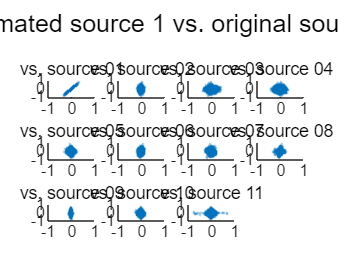

% ================= ICA 결과와 원본 소스 비교 =================
% Compare source 1 vs. original sources
fig_scat1 = figure;
for i = 1:size(down_S,1)
    subplot(3,4,i);
    scatter(down_S(i,:), down_xhat(1,:), 2, 'filled', ...
        'MarkerFaceAlpha', 0.3); 
    title(['vs. source ', sprintf('%02d', i)]);
    xlim([-1 1]); ylim([-1 1]);
end
sgtitle('Estimated source 1 vs. original sources');
drawnow;
saveas(fig_scat1, './plot/scatter_est1.png');

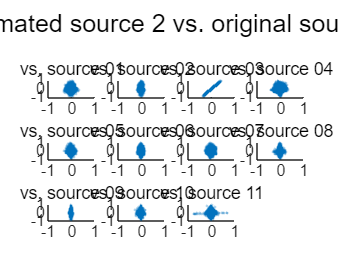


% Compare source 2 vs. original sources
fig_scat2 = figure;
for i = 1:size(down_S,1)
    subplot(3,4,i);
    scatter(down_S(i,:), down_xhat(2,:), 2, 'filled', ...
        'MarkerFaceAlpha', 0.3);
    title(['vs. source ', sprintf('%02d', i)]);
    xlim([-1 1]); ylim([-1 1]);
end
sgtitle('Estimated source 2 vs. original sources');
drawnow;
saveas(fig_scat2, './plot/scatter_est2.png');

% ============================================================

% Save Estimated Sources
for i = 1:size(X_hat, 1)
    fname = sprintf('./data/estimated_source%02d.wav', i);
    audiowrite(fname, X_hat(i, :)', fs);
end